# Diffractometry for NaCl

This script is computational proof that NaCl is a FCC structure. Furthermore, we compute some of its main parameters of intrest like the miller planes, average atomic radii workpreasure and grain-size.

clear; clc; clf

fileID = fopen('NaCl_XrayDifractomy.txt','r'); %read
formatSpec = '%f,%f';
sizeA = [2 Inf];
A = fscanf(fileID,formatSpec);

## Build Intensity and 2theta array

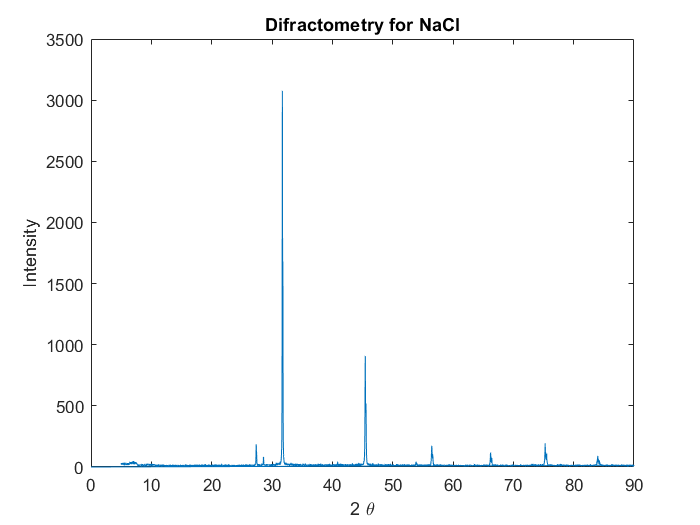

%Initialize
thet2 = zeros(1,size(A,1)); 
int = thet2;          

kk = 1;
jj = 1; 

%Build the arrays
for ii = 1:size(A,1)
    
    if ii/2 == round(ii/2)
        int(jj) = A(ii);
        jj = jj+1;
    else 
        thet2(kk)=A(ii);
        kk = kk+1;
    end
    
end
clear ii jj kk A fileID formatSpec sizeA
plot(thet2,int)
xlabel("2 \theta")
ylabel("Intensity")
title("Difractometry for NaCl")

thet2 = deg2rad(thet2);

## Define General Parameters

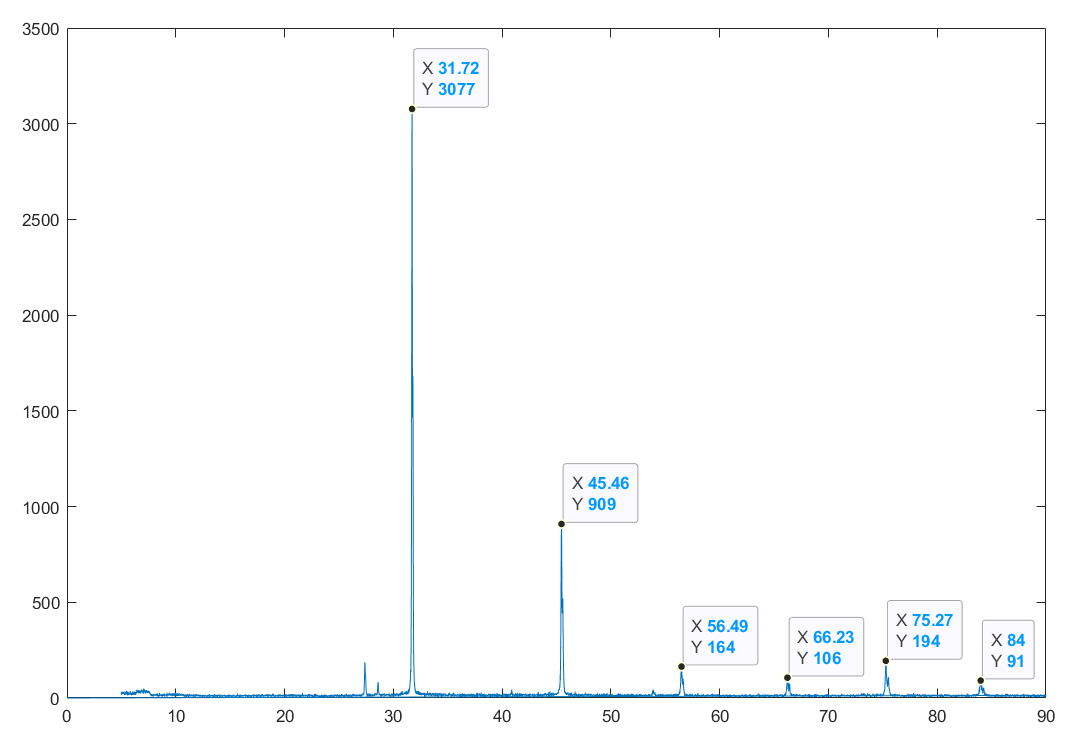

lambda = 1.54; %[A]

%Define General Parameters
%spikes = [27.38, 28.6, 31.72, 31.79, 45.47, 45.5, 56.49, 56.62, 66.24, 66.43, 75.27, 75.51, 83.99, 84.01];
spikes = [27.38, 31.72, 45.47, 53.87, 56.49];
index1 =  find(thet2 == deg2rad(spikes(1)),1);

%theta
theta= thet2./2;


## Find the indices

SC = [1,2,3,4,5,6,8,9,9,10,11,12,13,14,16,17];
BCC =[2,4,6,8,10,12,14,16,17];
FCC =[3,4,8,11,12,12];

%Initialize crystal patterns
sc = zeros(1,size(spikes,2));
bcc = sc;
fcc = sc;
d_hkl = sc;
r=sc;

bcc(1) =2 ;
fcc(1) =3 ;

%Build the arrays
for ii = 1:size(spikes,2)
    s = spikes(ii);
    index = find(thet2 == deg2rad(s),1);
    
    %create array to match the cubic structures
    sc(ii) = (sin(theta(index))^2)/sin(theta(index1))^2;
    bcc(ii) = sc(ii)*bcc(1);
    fcc(ii) = round(sc(ii)*fcc(1));  
    
    %calculate radii
    d_hkl(ii) = lambda/(2*sin(theta(index))); %Interplanar distance
    a = d_hkl(ii)*sqrt(SC(ii));     %Parametro de red
    r(ii) = a*sqrt(2)/4; %This formula depends on the type of structure. SC = a/2 || BCC = a sqrt(3)/4
end
clear index index1 ii s

We can observe a faced centered cubic (**FCC**) structure because the NaCl interlaps 2 SC structures in the faces. 

%Compare results to possible planes. 
SC_comp = cat(1,SC(1:size(sc,2)),sc) %plot possible plane numbers on top and calculated on bottom

SC_comp =     1.0000    2.0000    3.0000    4.0000    5.0000
    1.0000    1.3334    2.6665    3.6633    3.9984


BCC_comp = cat(1,BCC(1:size(sc,2)),bcc)%plot possible plane numbers on top and calculated on bottom

BCC_comp =     2.0000    4.0000    6.0000    8.0000   10.0000
    2.0000    2.6668    5.3331    7.3267    7.9968


FCC_comp = cat(1,FCC(1:size(sc,2)),fcc)%plot possible plane numbers on top and calculated on bottom

FCC_comp =      3     4     8    11    12
     3     4     8    11    12


comp = cat(1,sc,bcc,fcc)

comp =     1.0000    1.3334    2.6665    3.6633    3.9984
    2.0000    2.6668    5.3331    7.3267    7.9968
    3.0000    4.0000    8.0000   11.0000   12.0000



clear FCC_comp BCC_comp SC_comp comp

 On the other hand we can observe what is the value obtained for the **radii** of the cubic crystaline structure SC. Remember we need to compare it to the average of the whole structure (Na+Cl/2) 

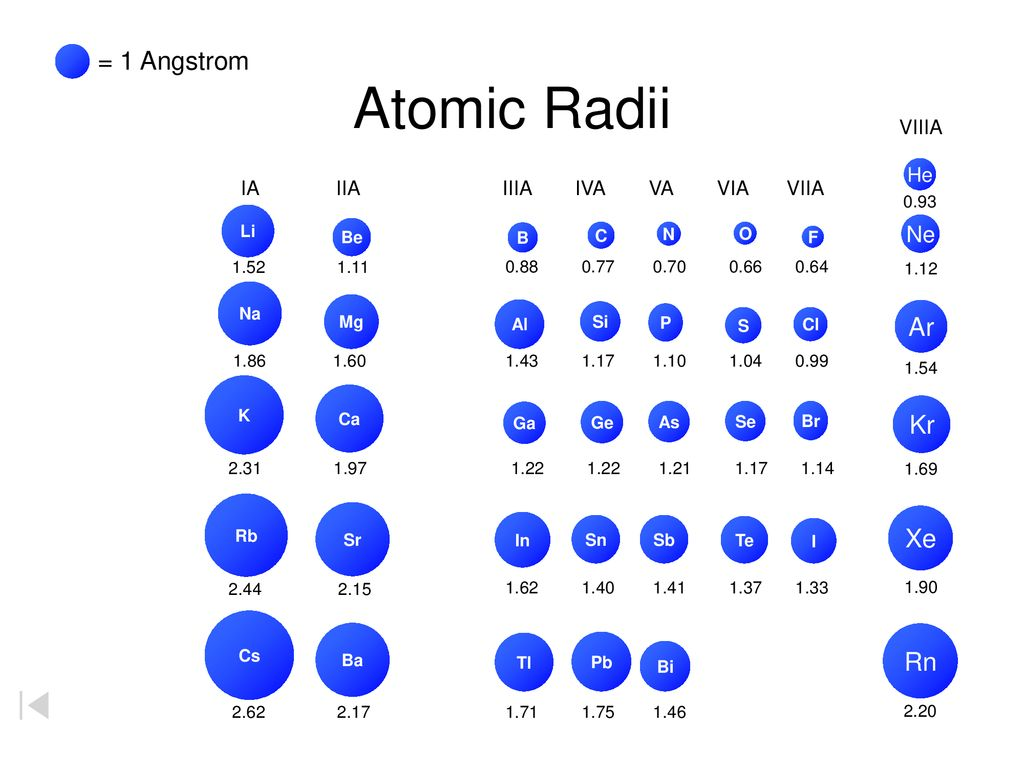

r_calc = mean(r)

r_calc = 1.2535

r_real = mean([1.8,0.9])

r_real = 1.3500

We can observe how in fact this matches this aspect of reality. 

Finaly we can find the miller indices for the planes of the structures by obtaining the valid planes

Planes = [100,110,111,200,210,211,220,221,300,310,311,222,320,321,400,322];
% SCvPlanes = [1,2,3,4,5,6,8,9,9,10,11,12,13,14,16,17];
% BCCvPlanes =[0,2,0,4,0,6,8,0,0,10,0,12,0,14,16,17];
FCCvPlanes =[0,0,3,4,0,0,8,0,0,0,11,12,0,0,12,0];

ii = find(FCCvPlanes>0,size(spikes,2))

ii =      3     4     7    11    12



Planes = Planes(ii)

Planes =    111   200   220   311   222


## Granular Structure

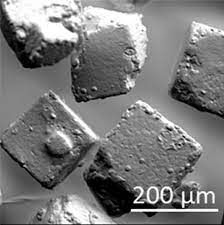

%Parameters
beta = 0.12; %[2thet-degrees]
K = 0.94;    %Scherrer cte for cubes

%Sherrer´s Law
for ii = 1:size(spikes,2)
    s = spikes(ii);
    index = find(thet2 == deg2rad(s),1);
    
    %create array 
    D(ii) = (K*lambda)/(beta*cos(theta(index))); %Grain diameter
    E(ii) = beta/(4*tan(theta(index)));          %Grain workpreasure    
end

D = mean(D) %Overall Grain size

D = 13.0523

E= mean(E)  %Overal Strenght

E = 0.0830

clear index ii s